# Demos: Convolutional Coding over Fading Channels

From the demo on uncoded modulation, we see that coding is essential for reliable transmission over fading channels. In this demo, we illustrate how to perform coded communicaiton over fading with a simple convolutional code.  In doing this demo, you will learn to:

- Measure the theoretical ergodic capacity by Shannon's formula

- Convolutional encode and decode data with MATLAB's convolutional encoder and decoder objects

- Perform MMSE equalization on faded symbols

- Compute LLRs on equalized symbols

- Add inter-leavers and de-interleavers 

## Ergodic Capacity

We next look at systems with coding.  We start with computing the theoretical ergodic capacity under a Rayleigh distribution.  Under Rayleigh fading, the SNR (in linear scale) can be modeled as:

where `u` is an exponential random varable with `E(u)=1. `The capacity on the channel on an AWGN channel and a channel with  fast fading are given by:

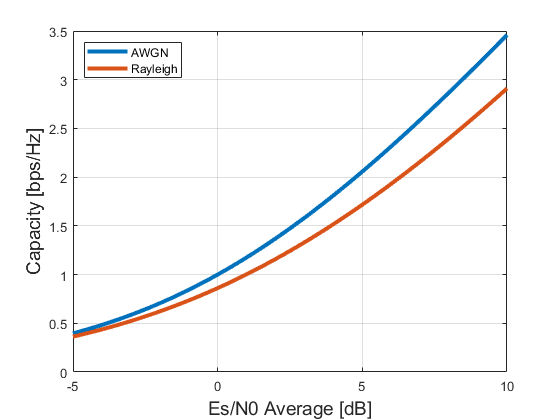

% Generate random fading levels
nu = 1e3;
u = exprnd(1,nu,1);

% Measure ergodic and flat capacity for each average SNR 
snrAvgTest = linspace(-5,10,100);
nsnr = length(snrAvgTest);
Cfading = zeros(nsnr,1);
Cflat = zeros(nsnr,1);
for i = 1:nsnr
    snr = snrAvgTest(i);
    Cflat(i) = log2(1 + db2pow(snr));
    Cfading(i) = mean(log2(1 + db2pow(snr)*u));    
end

% Plot results
clf;
plot(snrAvgTest, [Cflat Cfading], 'Linewidth', 3);
grid on;
legend('AWGN', 'Rayleigh', 'Location', 'northwest');
xlabel('Es/N0 Average [dB]', 'FontSize', 14);
ylabel('Capacity [bps/Hz]', 'FontSize', 14);

## Coding over a Flat Channel

We first illustrate coding with a simple convolutional coder over an AWGN channel.  We use a standard constraint length K=7 code:

% Create the convolutional encoder and decoder with constraint length K=7
trellis = poly2trellis(7,[171 133]);
convEnc = comm.ConvolutionalEncoder('TrellisStructure', trellis, 'TerminationMethod','Terminated');
convDec = comm.ViterbiDecoder('TrellisStructure', trellis, 'TerminationMethod','Terminated');

% Modulation 
bitsPerSym = 2;   % QPSK
M = 2^bitsPerSym;

% Number of information bits per block
nbits = 1000;

We now test the convolutional code at different SNR levels.

% SNR values to test
EbN0Test = (0:0.5:5)';
ntest = length(EbN0Test);
bler = zeros(ntest,1);

% Loop to test BLER
for i = 1:ntest
    EbN0 = EbN0Test(i);
    nerr = 0;
    nblk = 0;
    
    % Make sure you have either tested enough blocks or got a sufficient
    % number of errors 
    while  (nerr < 100) && (nblk < 1e4)
        
        % Generate random bits
        bitsIn = randi([0,1], nbits, 1);
        
        % Convolutionally encode the data
        bitsEnc = convEnc.step(bitsIn);
               
        % QAM modulate
        txSig = qammod(bitsEnc, M,'InputType','bit','UnitAveragePower',true);         
        
        % Add noise 
        rate = nbits/length(bitsEnc);
        Es = mean(abs(txSig).^2);
        EsN0 = EbN0 + 10*log10(rate*bitsPerSym);
        chan = comm.AWGNChannel('NoiseMethod', 'Signal to noise ratio (Es/No)', ...
            'EsNo', EsN0, 'SignalPower', Es);        
        rxSig = chan.step(txSig);
        
        % Compute LLRs
        noiseVar = Es*db2pow(-EsN0);
        llr = qamdemod(rxSig,M,'OutputType','approxllr', ...
            'UnitAveragePower',true,'NoiseVariance', noiseVar);        
       
        % Run Viterbi decoder.  We remove the tail bits
        bitsOut = convDec.step(llr);
        bitsOut = bitsOut(1:nbits);
        
        % Compute number of bit errors and add to the total
        if any(bitsIn ~= bitsOut)
            nerr = nerr + 1;
        end
        nblk = nblk + 1;
        
    end
    
    bler(i) = nerr / nblk;
    fprintf(1, 'EbN0 = %7.2f BLER=%12.4e\n', EbN0, bler(i));
    if nerr == 0
        break;
    end
end

EbN0 =    0.00 BLER=  1.0000e+00
EbN0 =    0.50 BLER=  1.0000e+00
EbN0 =    1.00 BLER=  1.0000e+00
EbN0 =    1.50 BLER=  9.4340e-01
EbN0 =    2.00 BLER=  7.6923e-01
EbN0 =    2.50 BLER=  3.5714e-01
EbN0 =    3.00 BLER=  1.0173e-01
EbN0 =    3.50 BLER=  2.3137e-02
EbN0 =    4.00 BLER=  5.9000e-03
EbN0 =    4.50 BLER=  5.0000e-04
EbN0 =    5.00 BLER=  2.0000e-04


We plot the results.  If we were to compare to uncoded modulation, we would see we do at least 4 dB better.

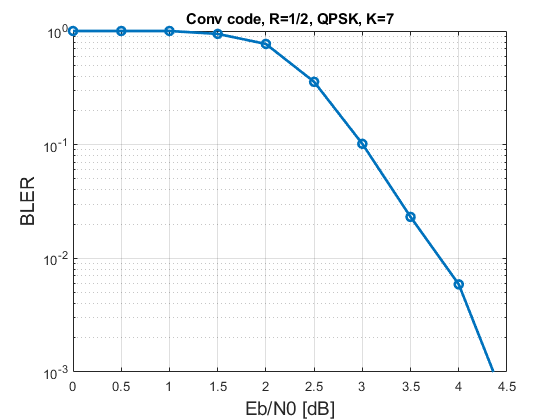

semilogy(EbN0Test, bler, 'o-', 'LineWidth', 2);
grid on;
ylim([1e-3,1]);
xlabel('Eb/N0 [dB]', 'FontSize', 14);
ylabel('BLER', 'Fontsize', 14);
title('Conv code, R=1/2, QPSK, K=7')

## Convolutional Coding and Decoding on a Fading Channel

We now test convolutional coding and decoding on a fading channel,  We use the same convolutional code as before.

% Create the convolutional encoder and decoder
trellis = poly2trellis(7,[171 133]);
convEnc = comm.ConvolutionalEncoder('TrellisStructure', trellis, 'TerminationMethod','Terminated');
convDec = comm.ViterbiDecoder('TrellisStructure', trellis, 'TerminationMethod','Terminated');

nsym = 1000;            % number of symbols per block
bitsPerSym = 2;         % number of bits per symbol
M = 2^bitsPerSym;       
nbits = nsym*bitsPerSym;    % Total number of coded bits


We now test both the flat and fading channel.  Note the addition of the interleaver, equalization and de-interleaver

% Channels ans SNRs to test
fadeTest = [false, true];
nfade = length(fadeTest);
EbN0Test = linspace(0,15,13);
ntest = length(EbN0Test);
bler = zeros(ntest,nfade);

% Main simulaiton loop
for j = 1:nfade
    fading = fadeTest(j);
        
    for i = 1:ntest
        EbN0 = EbN0Test(i);
        nerr = 0;
        nblk = 0;
        
        while  (nerr < 100) && (nblk < 1e3)
            
            % Generate random bits
            bitsIn = randi([0,1], nbits, 1);
            
            % Convolutionally encode the data
            bitsEnc = convEnc.step(bitsIn);            
            
            % Random interleaver
            state = randi(2^16,1);
            bitsInt = randintrlv(bitsEnc,state); 
            
            % QAM modulate
            txSig = qammod(bitsInt,M,'InputType','bit','UnitAveragePower',true);
            
            % Add fading
            nout = length(txSig);
            if fading
                h = sqrt(1/2)*(randn(nout,1) +1i*randn(nout,1));
            else
                h = ones(nout,1);
            end
            rxSig0 = h.*txSig;
            
            % Add noise at the sp
            rate = nbits/length(bitsEnc);
            Es = mean(abs(rxSig0).^2);
            EsN0 = EbN0 + 10*log10(rate*bitsPerSym);
            chan = comm.AWGNChannel('NoiseMethod', 'Signal to noise ratio (Es/No)', ...
                'EsNo', EsN0, 'SignalPower', Es);
            
            
            % Pass through AWGN channel
            rxSig = chan.step(rxSig0);
            
            % MMSE Equalize
            wvar = Es*10.^(-0.1*EsN0);
            z = conj(h).*rxSig ./ (abs(h).^2 + wvar);
            svar = 1;
            noiseVar = wvar*svar./(wvar + svar*abs(h).^2);
            
            % Compute LLRs
            llrInt = qamdemod(z,M,'OutputType','approxllr', ...
                'UnitAveragePower',true,'NoiseVariance', noiseVar);
            
            % De-interleave
            llr = randdeintrlv(llrInt,state); 
            
            % Run Viterbi decoder
            bitsOut = convDec.step(llr);
            bitsOut = bitsOut(1:nbits);
            
            % Compute number of bit errors and add to the total
            if any(bitsIn ~= bitsOut)
                nerr = nerr + 1;
            end
            nblk = nblk + 1;
            
        end
        
        bler(i,j) = nerr / nblk;
        fprintf(1, 'Fading=%d EbN0 = %7.2f BLER=%12.4e\n', fading, EbN0, bler(i,j));
        if nerr == 0
            break;
        end
    end
end

Fading=0 EbN0 =    0.00 BLER=  1.0000e+00
Fading=0 EbN0 =    1.25 BLER=  1.0000e+00
Fading=0 EbN0 =    2.50 BLER=  5.8824e-01
Fading=0 EbN0 =    3.75 BLER=  2.2000e-02
Fading=0 EbN0 =    5.00 BLER=  2.0000e-03
Fading=0 EbN0 =    6.25 BLER=  0.0000e+00
Fading=1 EbN0 =    0.00 BLER=  1.0000e+00
Fading=1 EbN0 =    1.25 BLER=  1.0000e+00
Fading=1 EbN0 =    2.50 BLER=  1.0000e+00
Fading=1 EbN0 =    3.75 BLER=  1.0000e+00
Fading=1 EbN0 =    5.00 BLER=  9.2593e-01
Fading=1 EbN0 =    6.25 BLER=  3.4483e-01
Fading=1 EbN0 =    7.50 BLER=  6.1000e-02
Fading=1 EbN0 =    8.75 BLER=  8.0000e-03
Fading=1 EbN0 =   10.00 BLER=  3.0000e-03
Fading=1 EbN0 =   11.25 BLER=  0.0000e+00


Plot the results

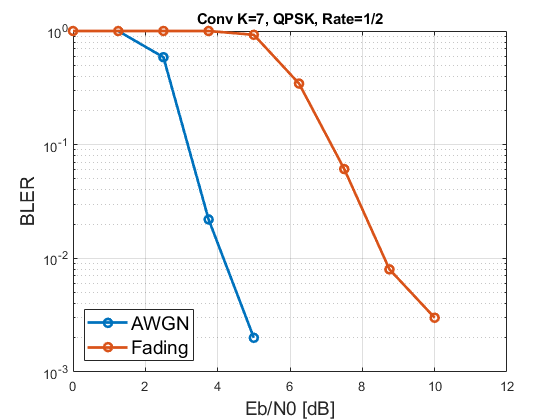

semilogy(EbN0Test, bler, 'o-', 'LineWidth', 2);
grid on;
ylim([1e-3,1]);
legend('AWGN', 'Fading', 'Location', 'SouthWest', 'FontSize', 14);
xlabel('Eb/N0 [dB]','FontSize',14);
ylabel('BLER','FontSize',14);
title('Conv K=7, QPSK, Rate=1/2')